## Exponential model

### Whichlacz and Unz (2002) data

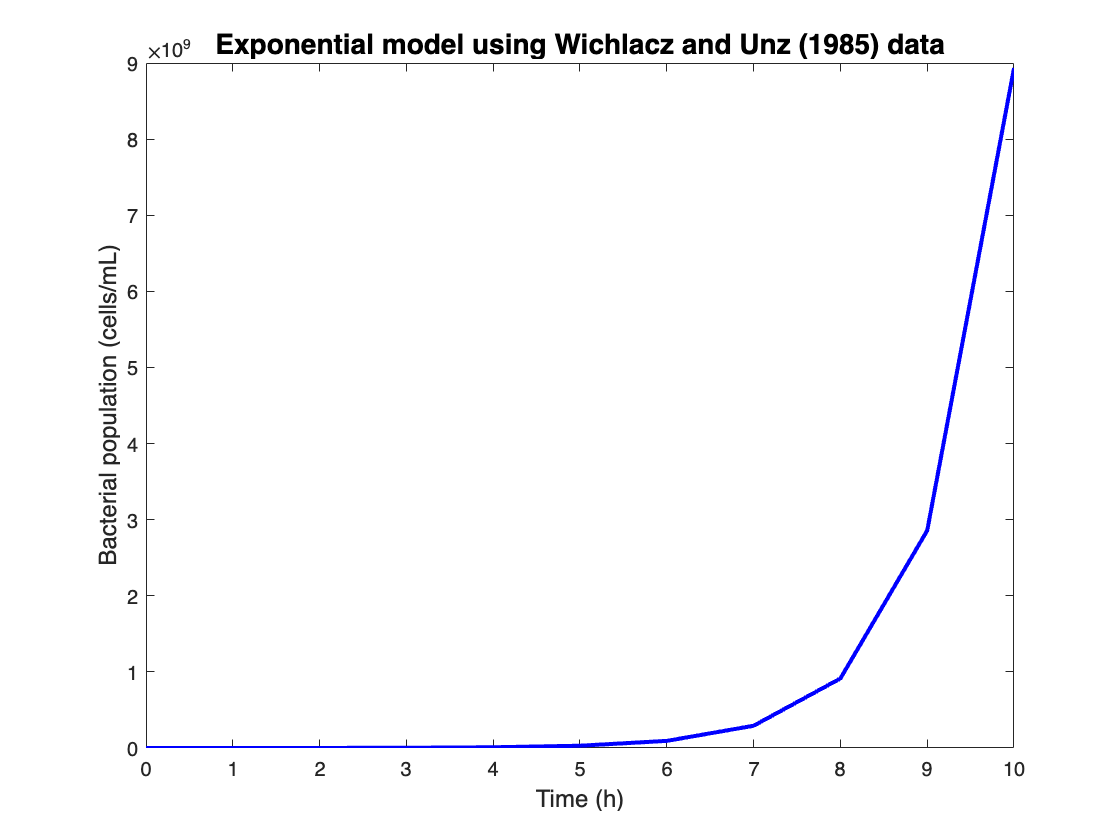

% Exponential model for bacterial growth kinetics
% N0 = initial bacterial population (cells/mL)
% k = specific growth rate (1/h)
% t = time (h)
% Nt = bacterial population at time t (cells/mL)

N0 = 1e5; % initial bacterial population
k = 1.14; % specific growth rate
t = 0:1:10; % time range (0 to 10 hours with 1 hour intervals)

Nt = N0 * exp(k * t); % exponential growth equation

figure
plot(t, Nt, 'b-', 'LineWidth', 2); % plot bacterial population over time
xlabel('Time (h)', 'FontSize', 12);
ylabel('Bacterial population (cells/mL)', 'FontSize', 12);
title('Exponential model using Wichlacz and Unz (1985) data', 'FontSize', 14);

### Yurt et al (2002) data

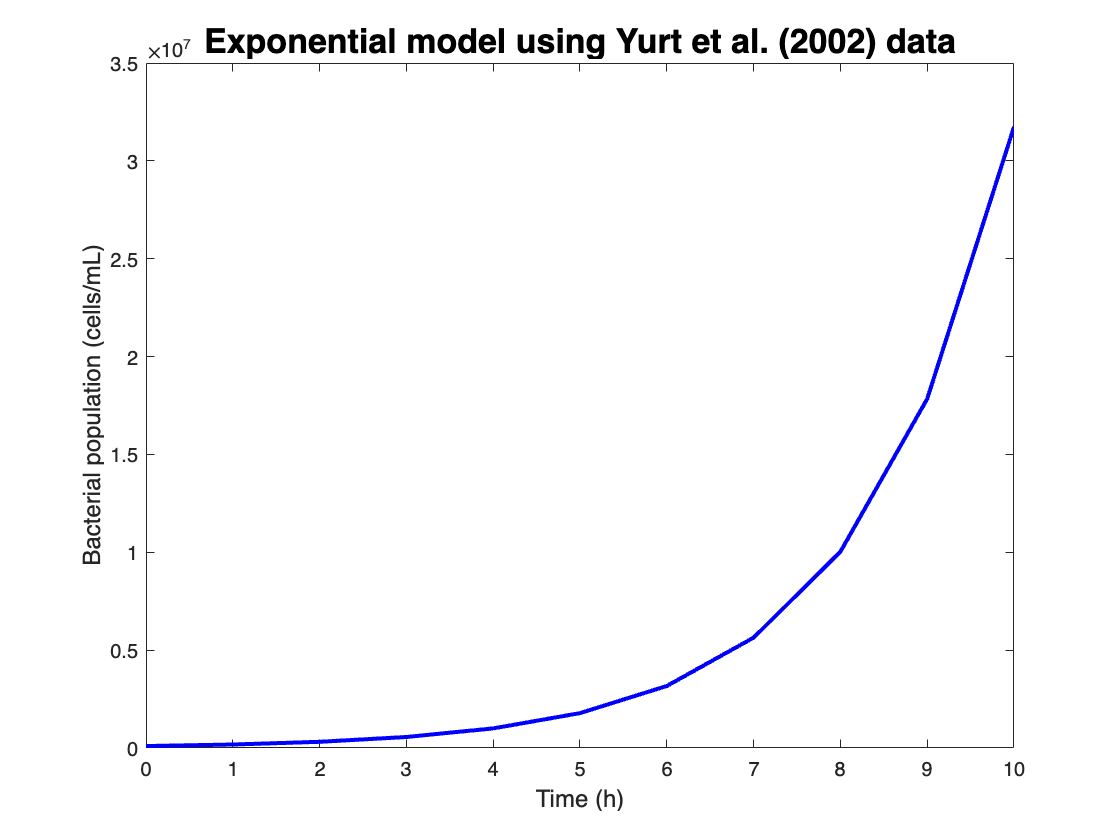

% Exponential model for bacterial growth kinetics
% N0 = initial bacterial population (cells/mL)
% k = specific growth rate (1/h)
% t = time (h)
% Nt = bacterial population at time t (cells/mL)

N0 = 1e5; % initial bacterial population
k = 0.576; % specific growth rate
t = 0:1:10; % time range (0 to 10 hours with 1 hour intervals)

Nt = N0 * exp(k * t); % exponential growth equation

figure
plot(t, Nt, 'b-', 'LineWidth', 2); % plot bacterial population over time
xlabel('Time (h)', 'FontSize', 12);
ylabel('Bacterial population (cells/mL)', 'FontSize', 12);
title('Exponential model using Yurt et al. (2002) data', 'FontSize', 17);

## Estimación de Parámetros de Datos Para la Capacidad de Carga en el Modelo Logístico

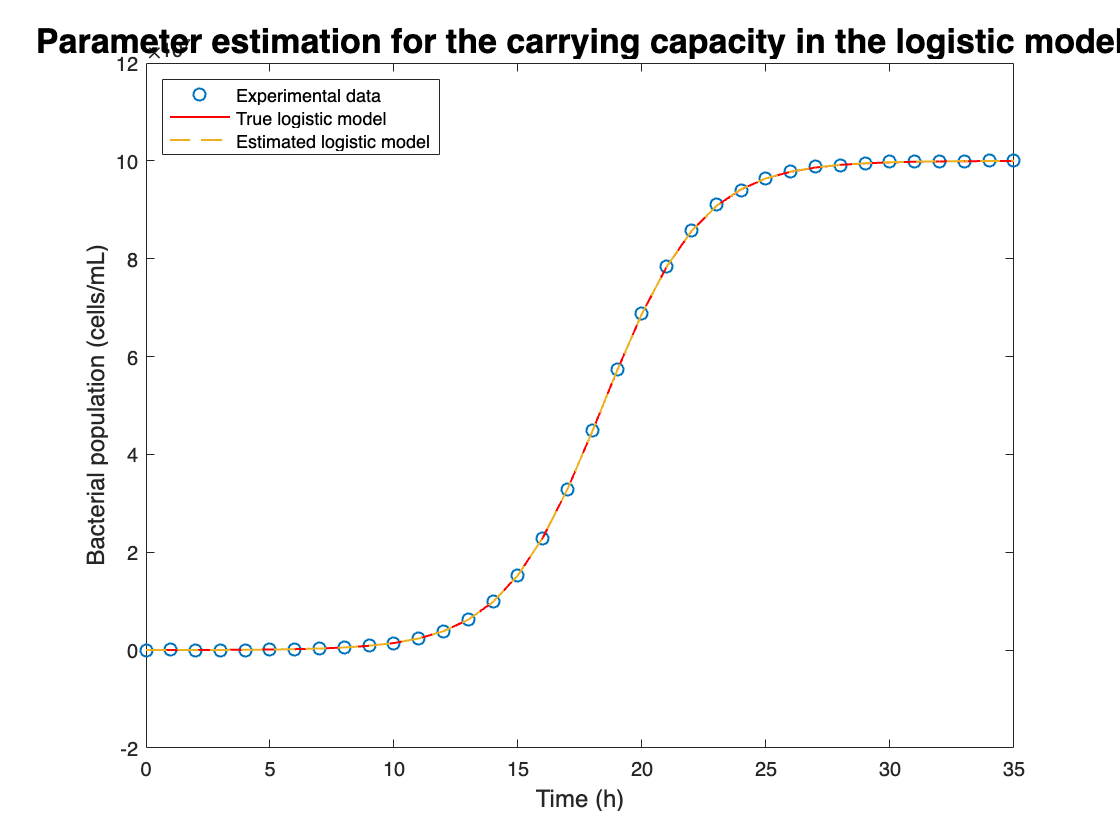

% Parameter estimation for the carrying capacity (K) in the logistic model
% N0 = initial bacterial population (cells/mL)
% k = specific growth rate (1/h)
% t = time (h)
% Nt = bacterial population at time t (cells/mL)
% K = carrying capacity (cells/mL)

% Generate experimental data
N0 = 1e4; % initial bacterial population
k = 0.5; % specific growth rate
t = 0:1:35; % time range (0 to 10 hours with 1 hour intervals)
K_true = 1e8; % true carrying capacity
Nt_true = K_true ./ (1 + ((K_true/N0)-1) * exp(-k*t)); % true bacterial population

% Add noise to the data
rng(1); % set random seed for reproducibility
sigma = 1e5; % standard deviation of the noise
Nt = Nt_true + sigma * randn(size(Nt_true)); % add noise to the true bacterial population

% Perform parameter estimation
fun = @(K) sum((Nt - K ./ (1 + ((K/N0)-1) * exp(-k*t))).^2); % objective function
K0 = 5e7; % initial guess for K
K_fit = fminsearch(fun, K0); % minimize the objective function to estimate K

% Plot the results
figure
plot(t, Nt, 'o', t, K_true ./ (1 + ((K_true/N0)-1) * exp(-k*t)), 'r-', 'LineWidth', 1);
hold on;
plot(t, K_fit ./ (1 + ((K_fit/N0)-1) * exp(-k*t)), '--', 'LineWidth', 1);
hold off;

xlabel('Time (h)', 'FontSize', 12);
ylabel('Bacterial population (cells/mL)', 'FontSize', 12);
legend('Experimental data', 'True logistic model', 'Estimated logistic model','Location', 'northwest');
title('Parameter estimation for the carrying capacity in the logistic model', 'FontSize',17);

## Logistic Model 

### Wichlacz and Unz (1985) data

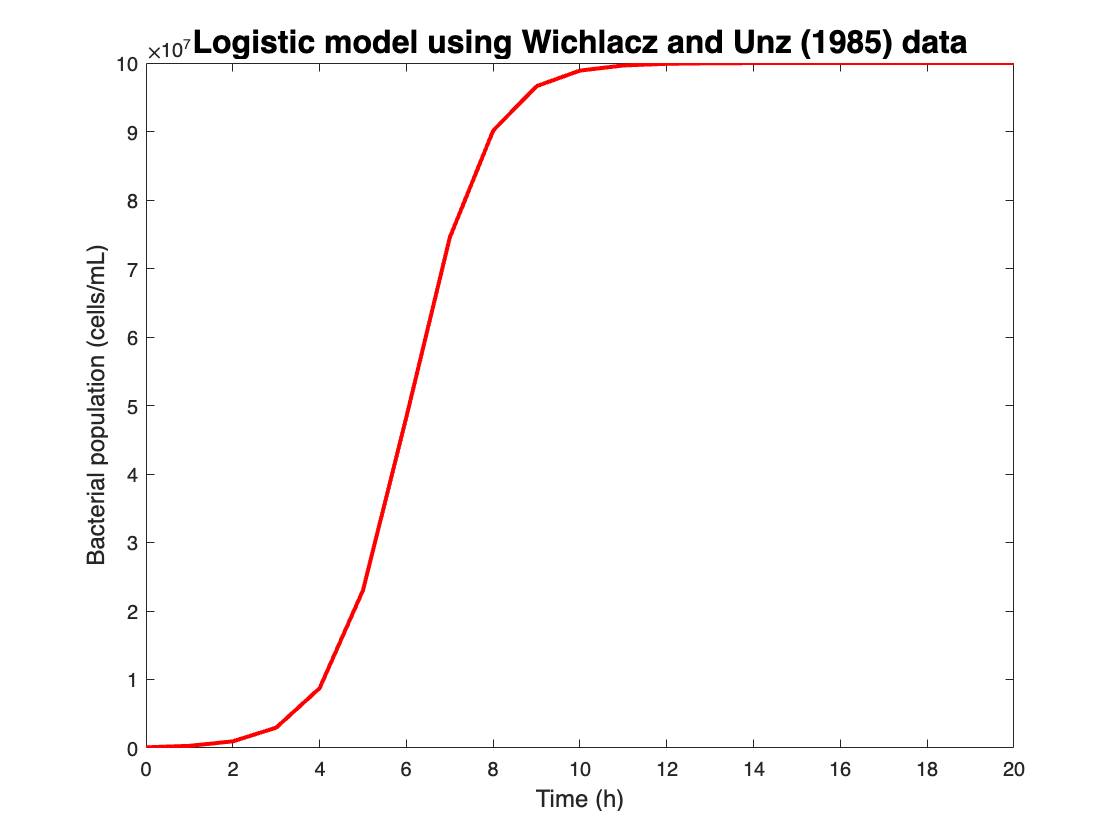

% Logistic model for bacterial growth kinetics
% N0 = initial bacterial population (cells/mL)
% k = specific growth rate (1/h)
% t = time (h)
% Nt = bacterial population at time t (cells/mL)
% K = carrying capacity (cells/mL)

N0 = 1e5; % initial bacterial population
k = 1.14; % specific growth rate Wichlacz and Unz (1985)
t = 0:1:20; % time range (0 to 10 hours with 1 hour intervals)
K = 1e8; % carrying capacity

Nt = K ./ (1 + ((K/N0)-1) * exp(-k*t)); % logistic growth equation

plot(t, Nt, 'r-', 'LineWidth', 2); % plot bacterial population over time
xlabel('Time (h)', 'FontSize', 12);
ylabel('Bacterial population (cells/mL)', 'FontSize', 12);
title('Logistic model using Wichlacz and Unz (1985) data', 'FontSize', 16);

### Yurt et al (2002) data

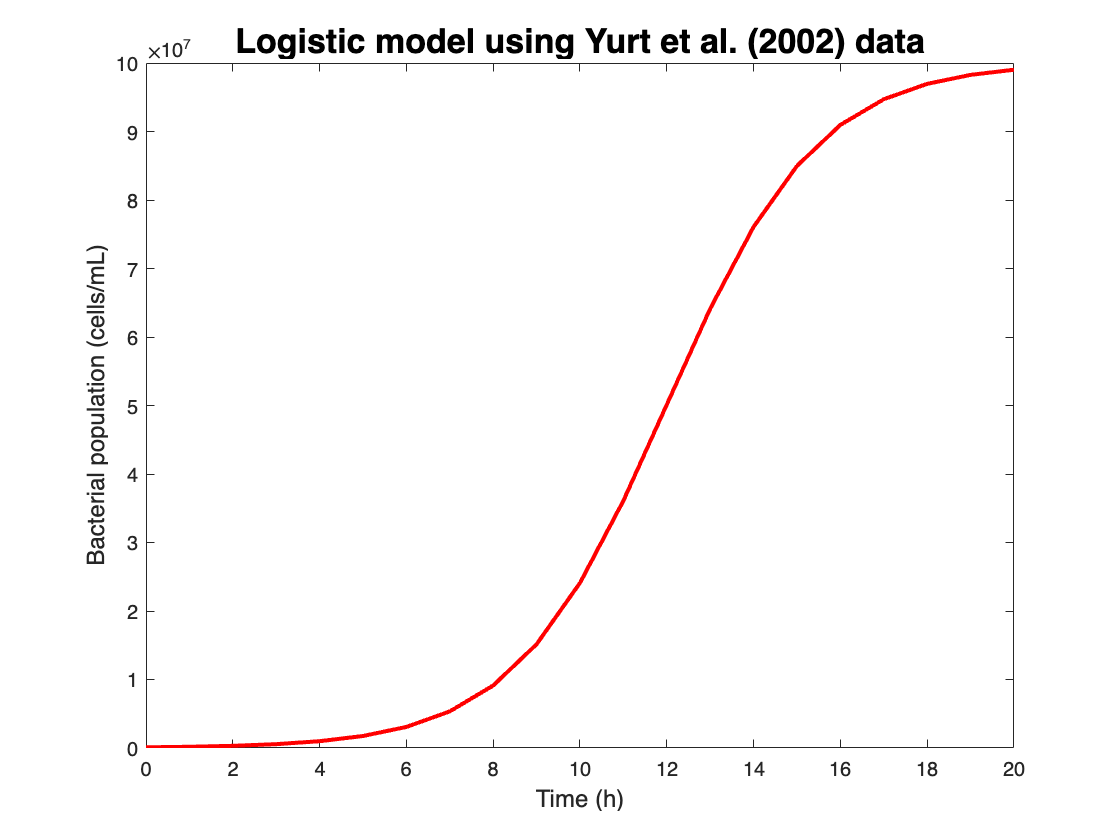

% Logistic model for bacterial growth kinetics
% N0 = initial bacterial population (cells/mL)
% k = specific growth rate (1/h)
% t = time (h)
% Nt = bacterial population at time t (cells/mL)
% K = carrying capacity (cells/mL)

N0 = 1e5; % initial bacterial population
k = 0.576; % specific growth rate Wichlacz and Unz (1985)
t = 0:1:20; % time range (0 to 10 hours with 1 hour intervals)
K = 1e8; % carrying capacity

Nt = K ./ (1 + ((K/N0)-1) * exp(-k*t)); % logistic growth equation

plot(t, Nt, 'r-', 'LineWidth', 2); % plot bacterial population over time
xlabel('Time (h)', 'FontSize', 12);
ylabel('Bacterial population (cells/mL)', 'FontSize', 12);
title('Logistic model using Yurt et al. (2002) data', 'FontSize',17);

## Gompertz model 

### Whichlacs and Unz (1985) data

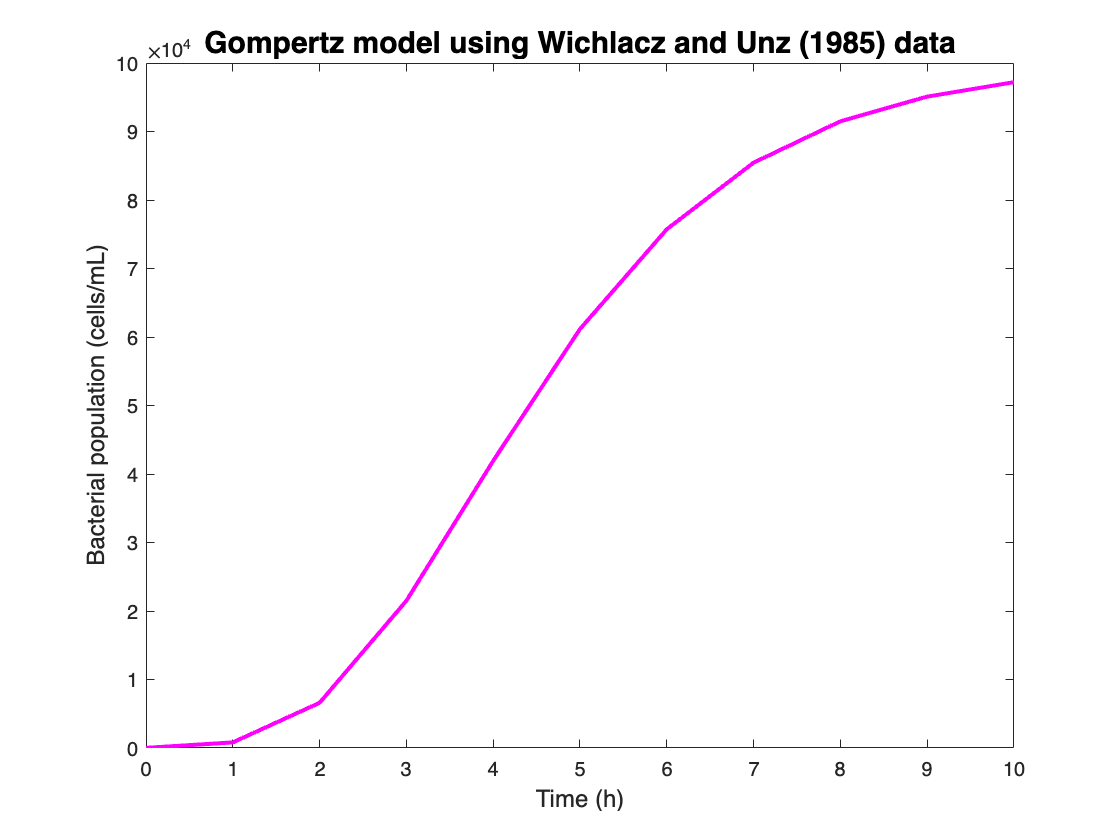

% Gompertz model for bacterial growth kinetics
% N0 = initial bacterial population (cells/mL)
% k = specific growth rate (1/h)
% t = time (h)
% mu = specific growth rate
% lambda = Retard phase duration
% Nt = bacterial population at time t (cells/mL)

N0 = 1e5; % initial bacterial population
mu = 1.14; % specific growth rate
t = 0:1:10; % time range (0 to 10 hours with 1 hour intervals)
lambda = 2;
e = 2;
Nt = N0 * exp(-exp((mu/e) * (lambda - t) + 1)); % gompertz growth equation

figure
plot(t, Nt, 'm-', 'LineWidth',2); % plot bacterial population over time
xlabel('Time (h)', 'FontSize', 12);
ylabel('Bacterial population (cells/mL)', 'FontSize', 12);
title('Gompertz model using Wichlacz and Unz (1985) data', 'FontSize',15);

### Yurt et al (2002) data

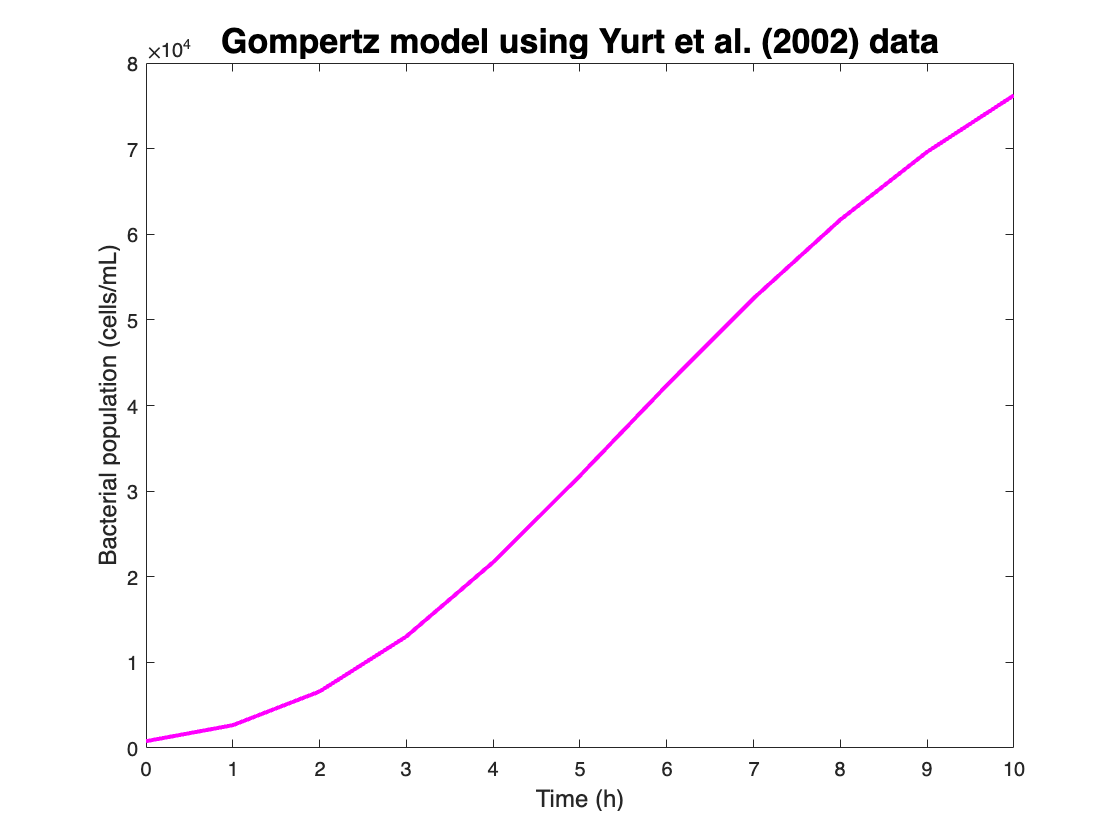

% Gompertz model for bacterial growth kinetics
% N0 = initial bacterial population (cells/mL)
% k = specific growth rate (1/h)
% t = time (h)
% mu = specific growth rate
% lambda = Retard phase duration
% Nt = bacterial population at time t (cells/mL)

N0 = 1e5; % initial bacterial population
mu = 0.576; % specific growth rate
t = 0:1:10; % time range (0 to 10 hours with 1 hour intervals)
lambda = 2;
e = 2;
Nt = N0 * exp(-exp((mu/e) * (lambda - t) + 1)); % gompertz growth equation

figure
plot(t, Nt, 'm-', 'LineWidth',2); % plot bacterial population over time
xlabel('Time (h)', 'FontSize', 12);
ylabel('Bacterial population (cells/mL)', 'FontSize', 12);
title('Gompertz model using Yurt et al. (2002) data', 'FontSize',17);